Parametric Identification

I'll now use a different model that applies a white noise input.  Of course this works just fine with the chirp as well...

sim('System_Identification_Parametric')
ydata = parametric_data(:,2);
udata = parametric_data(:,1);

Now build the ARMA model.

n = 2;  %Number of states
L = length(ydata);
X = [];
Y = [];
for ii = n+1:L
    y = [];
    u = [];
    for jj = 1:n
        y = [y -ydata(ii-jj)];
        u = [u udata(ii-jj)];
    end
    X = [X;[y,u]];
    Y = [Y;ydata(ii)];
end

Time for the pseudo-inverse solution.  The pinv operation in Matlab completes this for me.

theta = pinv(X)*Y

theta =    -1.9990
    0.9990
    0.0000
    0.0000


Now build the model that uses it.  Remember, this is a discrete-time model!

Gmod = tf(theta(3:end)',[1 theta(1:2)'],1/1000)


Gmod =
 
  4.998e-07 z + 4.997e-07
  -----------------------
   z^2 - 1.999 z + 0.999
 
Sample time: 0.001 seconds
Discrete-time transfer function.



Let's now test the fit quality.

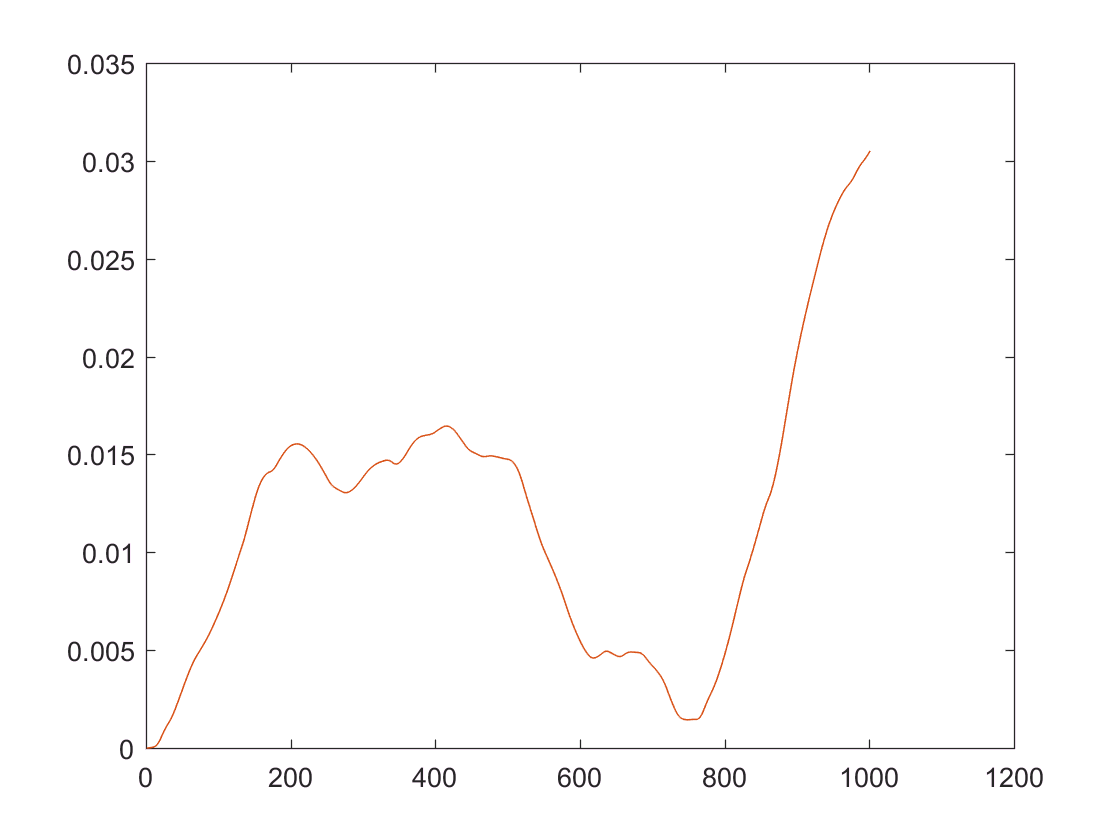

ymod = lsim(Gmod,udata,[0:.001:0.001*(length(udata)-1)]);
plot([ydata,ymod])

Looks awesome!  Now, convert to CT to compare with our other answer.

Gmod_CT = d2c(Gmod)


Gmod_CT =
 
  1.669e-10 s + 1
  ---------------
    s^2 + s + 5
 
Continuous-time transfer function.



Looks great to me!